Initial Conditions

x_0 = [10; 0; 10; 0; 20; 0]

x_0 =     10
     0
    10
     0
    20
     0


  Solvuing the Non Linear

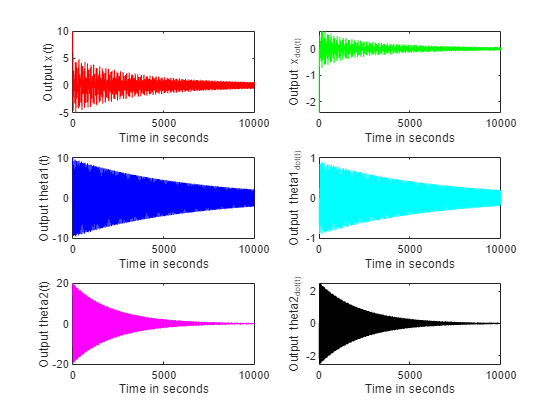

%defining the timespan
    tspan = 0:0.01:10000; 
%usindg ode45 function for definining a diff eqn
    [t,x] = ode45(@nonlinear,tspan,x_0); 
%plotting the function output on a 2D graph
    subplot(3, 2, 1);
    plot(t,x(:,1),'r')
    xlabel('Time in seconds')
    ylabel('Output x(t)')
    subplot(3, 2, 2);
    plot(t,x(:,2),'g')
    xlabel('Time in seconds')
    ylabel('Output x_dot(t)')
    subplot(3, 2, 3);
    plot(t,x(:,3),'b')
    xlabel('Time in seconds')
    ylabel('Output theta1(t)')
    subplot(3, 2, 4);
    plot(t,x(:,4),'c')
    xlabel('Time in seconds')
    ylabel('Output theta1_dot(t)')
    subplot(3, 2, 5);
    plot(t,x(:,5),'m')
    xlabel('Time in seconds')
    ylabel('Output theta2(t)')
    subplot(3, 2, 6);
    plot(t,x(:,6),'k')
    xlabel('Time in seconds')
    ylabel('Output theta2_dot(t)')

function x_dot = nonlinear(t,x)


M_val = 1000;
m1_val = 100;
m2_val = 100;
l1_val = 20;
l2_val = 10;
g_val = 9.81;

%Linearized equations
A = [0 1 0 0 0 0;
    0 0 (-g_val*m1_val)/M_val 0 (-g_val*m2_val)/M_val 0;
    0 0 0 1 0 0;
    0 0 -(g_val*(M_val+m1_val))/(M_val*l1_val) 0 -(g_val*m2_val)/(M_val*l1_val) 0;
    0 0 0 0 0 1;
    0 0 -(g_val*m1_val)/(M_val*l2_val) 0 -(g_val*(M_val+m2_val))/(M_val*l2_val) 0];
B = [0;
    1/M_val;
    0;
    1/(M_val*l1_val);
    0;
    1/(M_val*l2_val)];

% Defining Q and R for LQR definition
Q = [1000 0 0 0 0 0;  %x penalize
    0 100 0 0 0 0;   %x_dot penalize
    0 0 100 0 0 0;   %theta1 penalize
    0 0 0 100 0 0;   %theta1_dot penalize
    0 0 0 0 100 0;   %theta2 penalize
    0 0 0 0 0 100];  %theta2_dot penalize

R = 0.001;

% K from LQR
[K,~,~] = lqr(A, B, Q, R);

% Input eqaution
F = -K*x;

% Initial x_dot condition
x_dot = zeros(6,1);

% Defining the x_dot matrix
% x_dot(1) = X_dot
x_dot(1) = x(2);

%x_dot(2) = X_dotdot
x_dot(2) = (-(m1_val*g_val*sind(x(3))*cosd(x(5))) -(m2_val*g_val*sind(x(5))*cosd(x(5))) -(m1_val*l1_val*(x(4))*(x(4))*sind(x(3))) -(m2_val*l2_val*(x(6))*(x(6))*sind(x(5))) +F)/(M_val +m1_val*(1-cosd(x(3))^2) +m2_val*(1-cosd(x(5))^2));

%x_dot(3) = theta1_dot
x_dot(3) = x(4);

%x_dot(4) = theta1_dotdot
x_dot(4) = (x_dot(2)*cosd(x(3))-g_val*(sind(x(3))))/l1_val';

%x_dot(5) = theta2_dot
x_dot(5) = x(6);

%x_dot(6) = theta2_dotdot
x_dot(6) = (x_dot(2)*cosd(x(5))-g_val*(sind(x(5))))/l2_val';

end

